# Prepare

clear all, close all, clc
global A

## Task 1

System equations

b = [1 3];
a = [1 1.1 10];
% Transfer function model to check
systf = tf([1 3],[1 1.1 10])


systf =
 
       s + 3
  ----------------
  s^2 + 1.1 s + 10
 
Continuous-time transfer function.



% Convert to state space
[A,B,C,D] = tf2ss(b,a);

sys = ss(A,B,C,D)


sys =
 
  A = 
         x1    x2
   x1  -1.1   -10
   x2     1     0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   1   3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



## Task 2

Rank of controllability and observability matrices

Cont = rank([sys.B, sys.A*sys.B])

Cont = 2

ContU = rank([sys.C*sys.B, sys.C*sys.A*sys.B])

ContU = 1

Obs = rank([sys.C; sys.C*sys.A])

Obs = 2

## Task 3

Make system matrix global

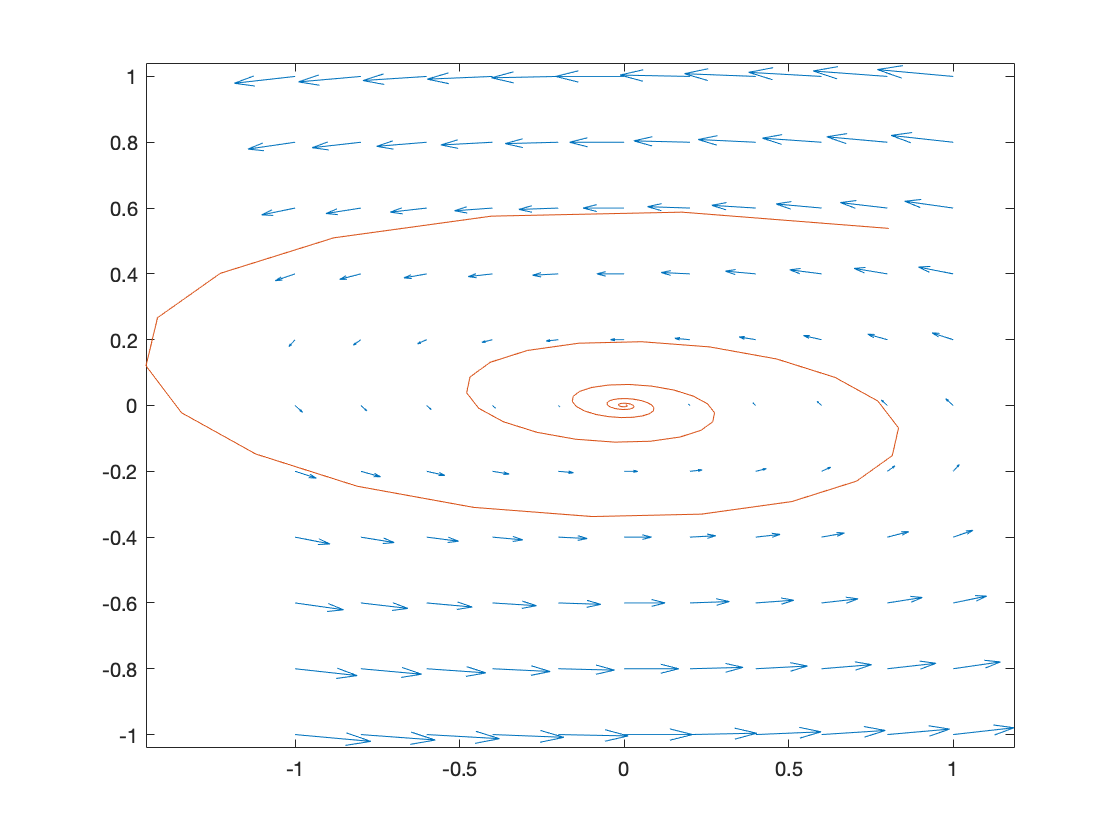

A = sys.A;
% Function to calculate derivatives
xdot = @(x) A*x;

% Range and resolution
res = 11;
x1 = linspace(-1, 1, res);
x2 = linspace(-1, 1, res);
[X1, X2] = meshgrid(x1,x2);
x = [reshape(X1, [1, res*res]);reshape(X2, [1, res*res])];
y = xdot(x);
% System Trajektory
t = linspace(0,10);
[ytra, t, xtra] = lsim(sys, zeros(size(t)), t, rand(2,1));
% Plot
quiver(X1, X2, reshape(y(1,:), [res,res]), reshape(y(2,:), [res, res]));
hold on
plot(xtra(:,1), xtra(:,2))
axis equal